##                                                       Robótica - Lista de Exercícios 2

**                        Nome: **Marcos Carvalho Ferreira                                                                            **Matrícula:** 202010203

import RoboticaBiblioteca.*
printListaManipuladores()

Unrecognized function or variable 'printListaManipuladores'.

**Questão 1**

Calcule $p_0$ conforme $p_1$ e $H_0^1$ abaixo:

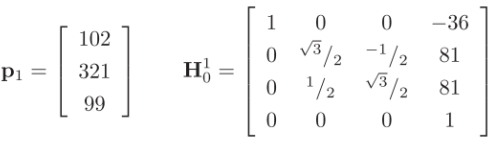


$$P_1 =H_0^1 P_0$$


p1 = [102 ; 321 ; 99];
H10 = [1 0 0 -36;
       0 sqrt(3)/2 -1/2 81;
       0 1/2 sqrt(3)/2 81;
       0 0 0 1];
P1 = [p1 ; 1];
P0 = H10^-1 * P1

**Questão 2**

Seja a célula de trabalho mostrada na figura abaixo e dados os referenciais {B} (Base), {G} (Garra}, {E} (Estação) e {O} (Objeto}; determinar GTO a partir das transformações homogêneas conhecidas BTG , BTE , ETO.

                                                                            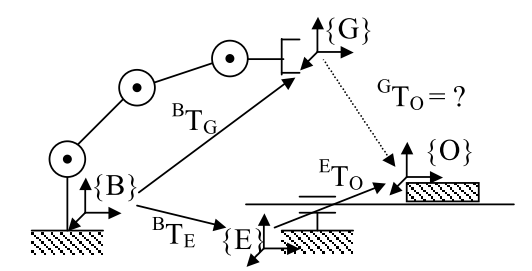

BTO = BTE * ETO

BTO = BTG * GTO

BTG * GTO = BTE * ETO

(BTG)^-1 * BTG * GTO = (BTG)^-1 * BTE * ETO

I * GTO = (BTG)^-1 * BTE * ETO

GTO = (BTG)^-1 * BTE * ETO

**Questão 3**

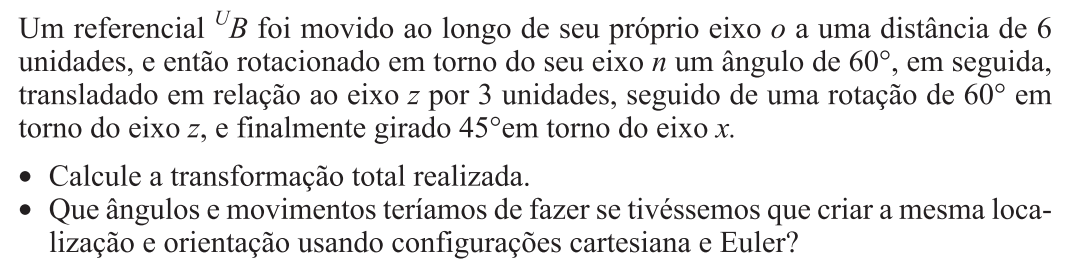

% Enunciado: trans('o',6) --> rot('n',60) --> trans('z',3) --> rot('z',60) --> rot('x',45)
B = trans(0,0,0)
B = rot('x',45)*rot('z',60)*trans(0,0,3)*B*trans(0,6,0)*rot('n',60)
% Cartesiano - Euler
%    PPP     - RRR
movimentosTcart(B(1,4),B(2,4),B(3,4));
angsEuler(B);

**Questão 4**

Find the rotation matrix representing a roll of π/4 followed by a yaw of π/2 followed by a pitch of π/2.

matrizRot('x',180/4)*matrizRot('z',180/2)*matrizRot('y',180/2)

**Questão 5**

Suppose that three coordinate frames o1x1y1z1, o2x2y2z2 and o3x3y3z3 are given, and suppose

              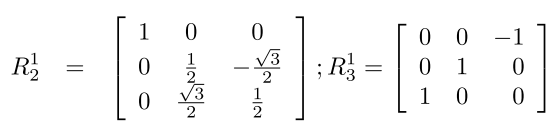

Find the matrix 𝑅32.


$$\begin{array}{l}
R_3^1 =R_2^1 R_3^2 \\
{R_2^1 }^{-1} R_3^1 =R_3^2 
\end{array}$$


R12 = [1 0 0;
       0 1/2 -sqrt(3)/2;
       0 sqrt(3)/2 1/2];
R13 = [0 0 -1;
       0 1 0;
       1 0 0];
R23 = R12^-1 * R13

**Questão 7**

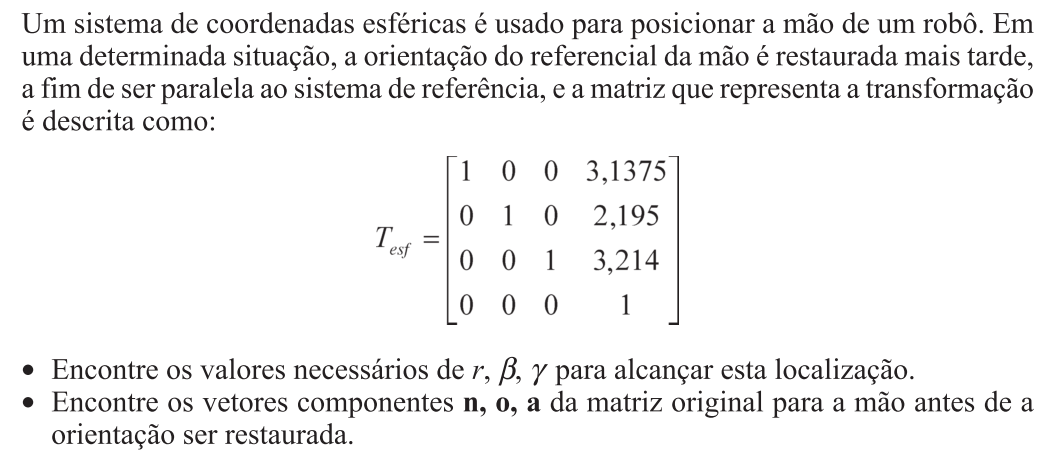

**a)**

[r, beta, gama] = movimentosTesf(3.1375,2.195,3.214);

**b) **

Tesf(r,beta,gama)

**Questão 8**

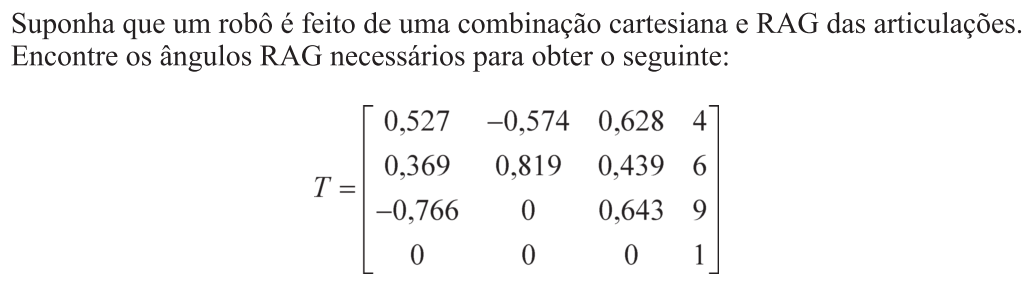

[Px, Py, Pz] = movimentosTcart(4,6,9);
[ThetaN, ThetaO, ThetaA] = angsRAG([0.527 -0.574 0.628 4;
                                    0.369 0.819 0.439 6;
                                    -0.766 0 0.643 9;
                                    0 0 0 1]);
rotRAG(ThetaA,ThetaO,ThetaN)
syms phi theta psi;
rotRAG(phi, theta, psi)

**Questão 9**

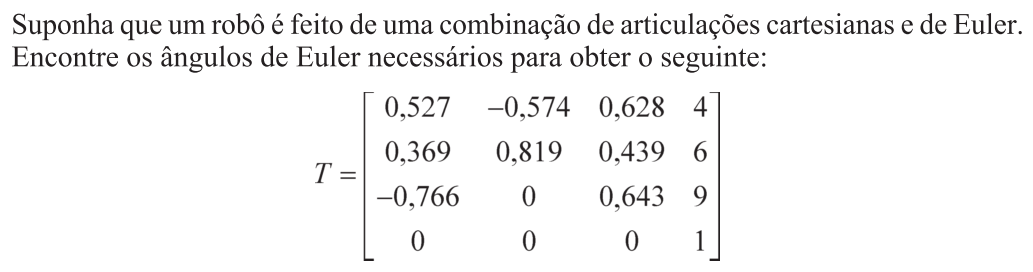

[Px, Py, Pz] = movimentosTcart(4,6,9);
[Phi, Theta, Psi] = angsEuler([0.527 -0.574 0.628 4;
                               0.369 0.819 0.439 6;
                              -0.766 0 0.643 9;
                               0 0 0 1]);
rotZYZ(Phi, Theta, Psi)

**Questão 10**

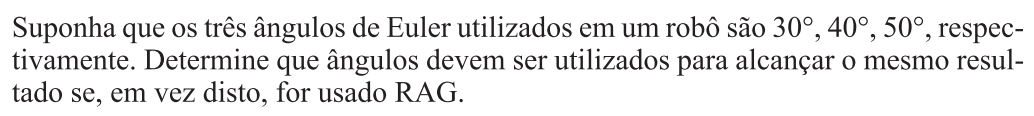

Matriz = rotZYZ(30,40,50)
[ThetaN, ThetaO, ThetaA] = angsRAG(Matriz);
confusao()
rotRAG(ThetaA, ThetaO, ThetaN)

**Questão 11**

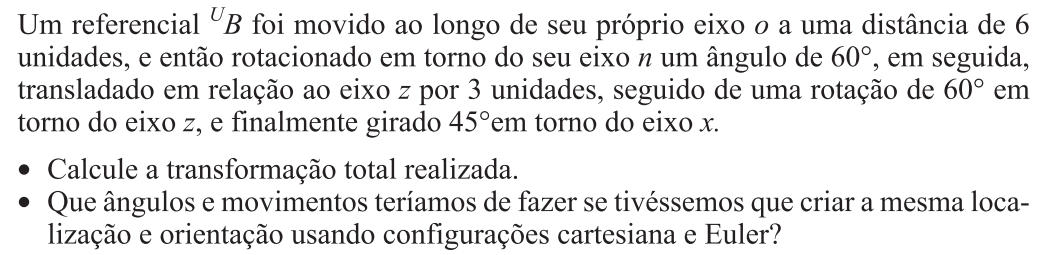

B = trans(0,0,0)
B = rot('x',45)*rot('z',60)*trans(0,0,3)*B*trans(0,6,0)*rot('n',60)
[Phi, Theta, Psi] = angsEuler(B);